counter = 1

counter = 2

counter = 3

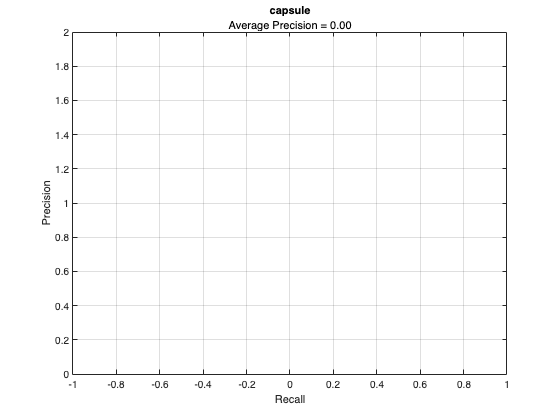

counter = 4

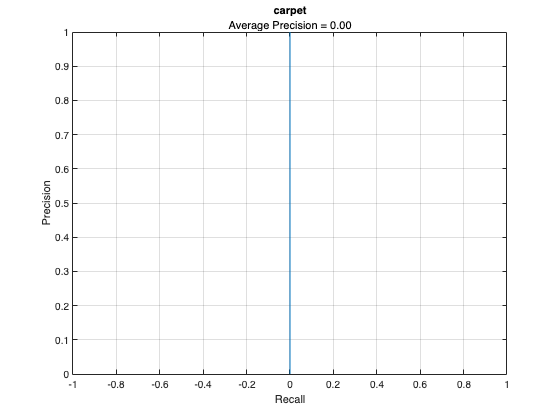

counter = 5

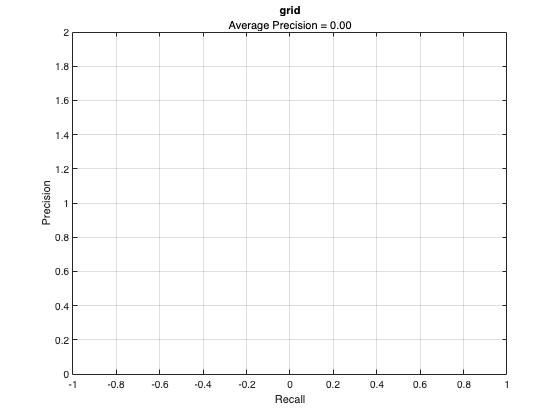

counter = 6

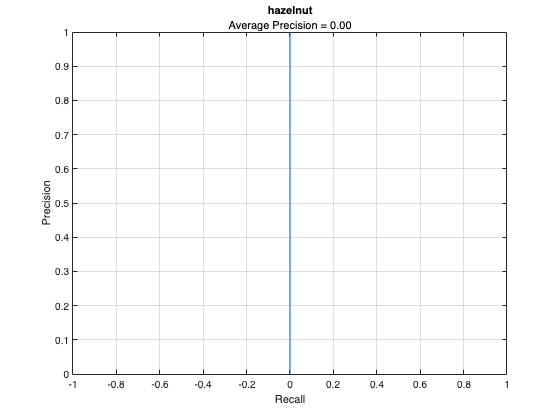

counter = 7

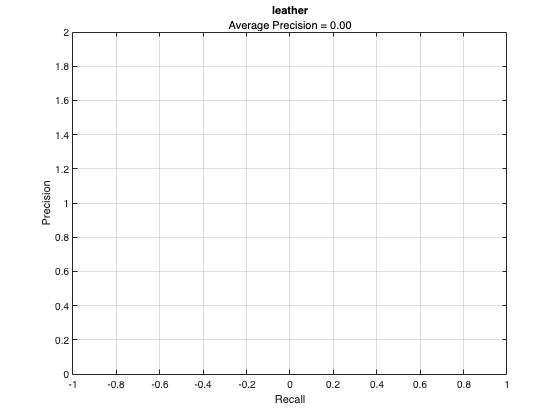

counter = 8

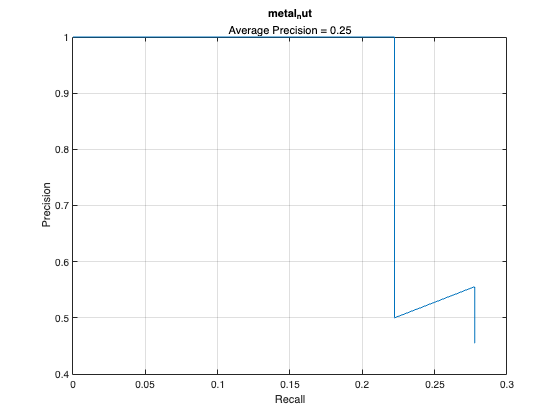

counter = 9

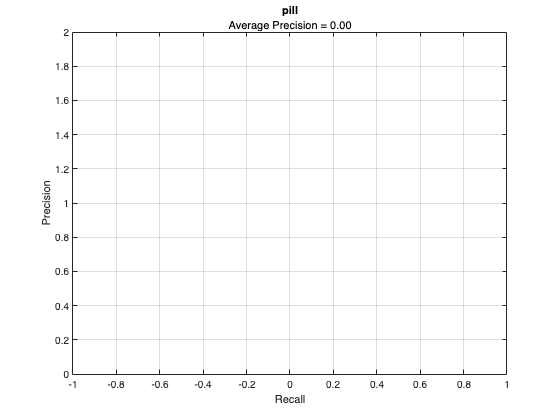

counter = 10

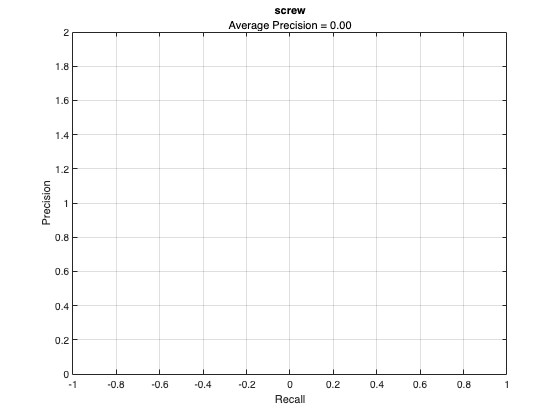

counter = 11

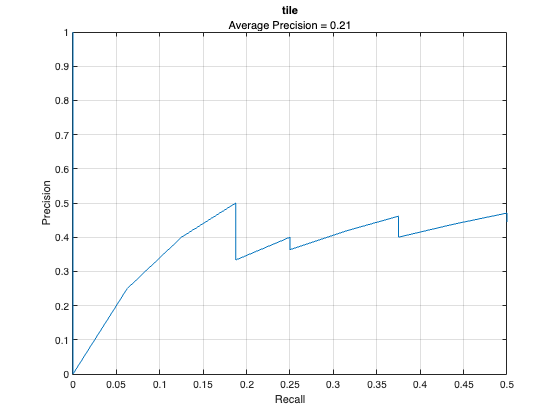

counter = 12

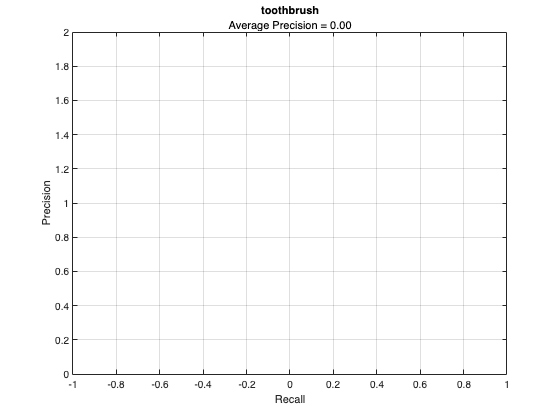

counter = 13

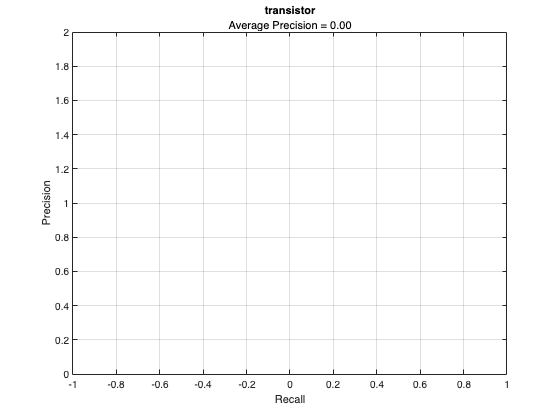

counter = 14

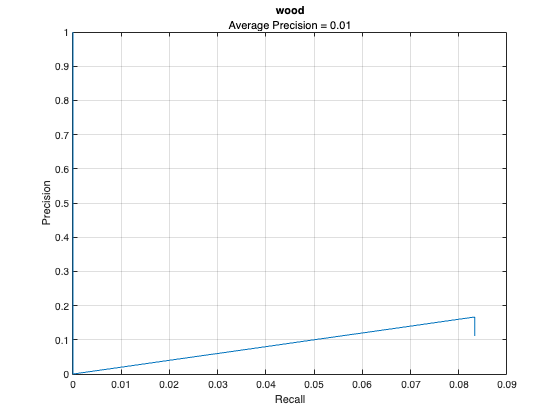

counter = 15

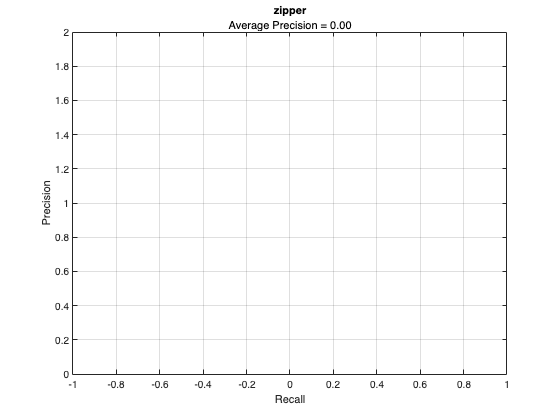

clc;
clear;
close all;

load("element.mat")
% element(1).name
load("/Users/frederikplahl/Downloads/models.mat")

for counter = 1:width(element)
    counter
    imdsTestData = imageDatastore(string(element(counter).data_test{:,'imageFilename'}));
    bldsTestData = boxLabelDatastore(element(counter).data_test(:,'error'));

    inputSize = [224 224 3];

    testData = combine(imdsTestData,bldsTestData);
    testData = transform(testData,@(data)preprocessData(data,inputSize));

    detectionResults = detect(models(counter).detector,testData,'MinibatchSize',4);

    [ap, recall, precision] = evaluateDetectionPrecision(detectionResults,testData);

    figure
    plot(recall,precision)
    xlabel('Recall')
    ylabel('Precision')
    grid on
    title(element(counter).name,sprintf('Average Precision = %.2f', ap))
end

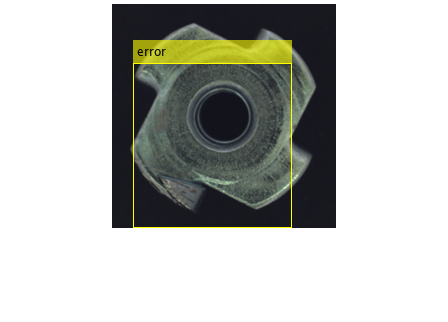

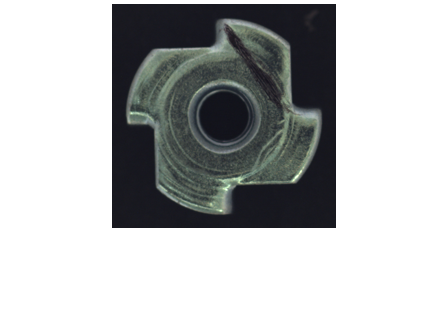

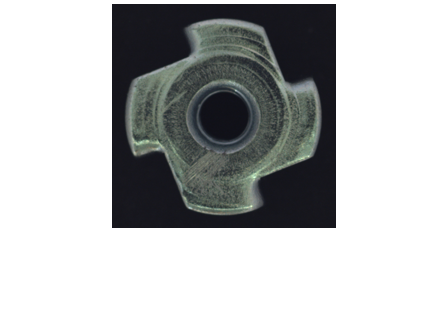

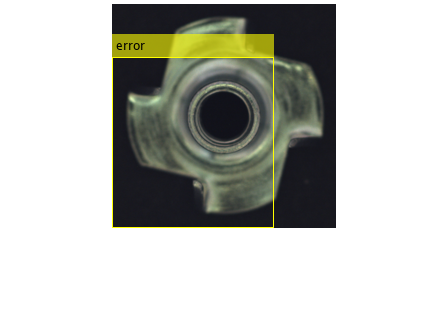

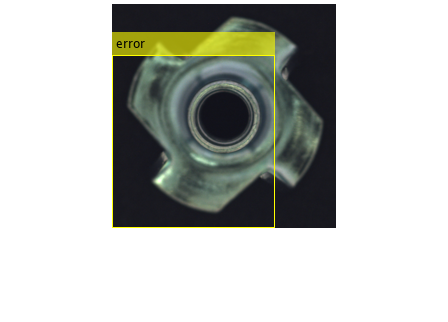

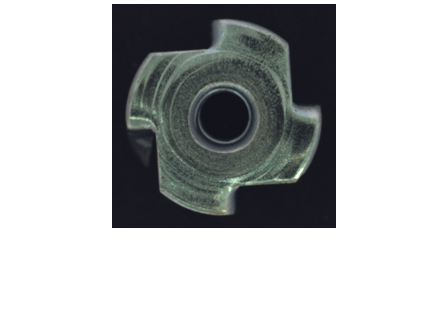

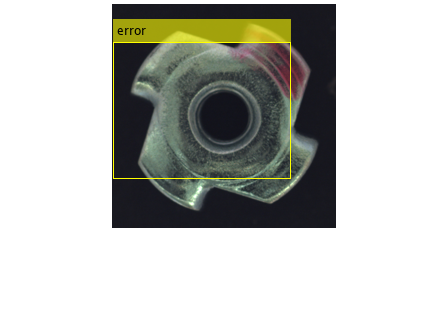

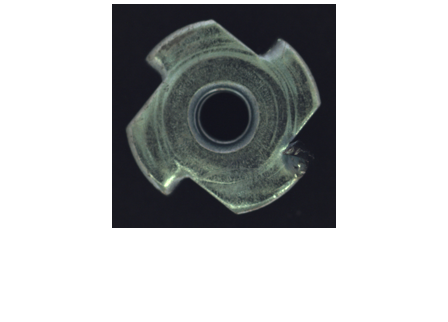

for counter = 1:width(element)
    if element(counter).name=="metal_nut" || element(counter).name=="tile"
        for k = 1:height(element(counter).data_test)
            I = imread(element(counter).data_test.imageFilename{k});
            I = imresize(I,inputSize(1:2));
            [bboxes,scores, label] = detect(models(counter).detector,I);
            I = insertObjectAnnotation(I,'rectangle',bboxes,label);
            figure
            imshow(I)
        end
    end
end

function data = augmentData(data)
% Randomly flip images and bounding boxes horizontally.
tform = randomAffine2d('XReflection',true);
sz = size(data{1});
rout = affineOutputView(sz,tform);
data{1} = imwarp(data{1},tform,'OutputView',rout);

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Warp boxes.
data{2} = bboxwarp(data{2},tform,rout);
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to targetSize.
sz = size(data{1},[1 2]);
scale = targetSize(1:2)./sz;
data{1} = imresize(data{1},targetSize(1:2));

% Sanitize box data, if needed.
% data{2} = helperSanitizeBoxes(data{2}, sz);

% Resize boxes.
data{2} = bboxresize(data{2},scale);
end